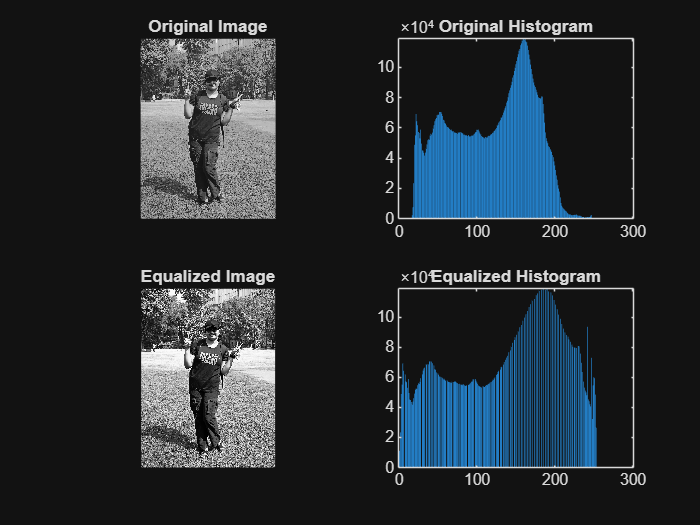

%% Histogram Equalization Script

% 1. Read the image and convert to double for calculation
a = imread('DK.jpg'); % You can also try 'pout.tif'
a = rgb2gray(a);
a = double(a);

% 2. Get image dimensions and max intensity
big = max(max(a)); 
[row, col] = size(a);
C = row * col; % Total number of pixels

% 3. Pre-allocate arrays for histograms (Original and Equalized)
h = zeros(1, 300); 
z = zeros(1, 300);

% 4. Ensure no zero values (to avoid indexing errors in MATLAB)
for n = 1:row
    for m = 1:col
        if a(n,m) == 0
            a(n,m) = 1;
        end
    end
end

% 5. Calculate Histogram of original image
for n = 1:row
    for m = 1:col
        t = a(n,m);
        h(t) = h(t) + 1;
    end
end

% 6. Calculate Probability Density Function (PDF) and Cumulative Distribution Function (CDF)
pdf = h / C;
cdf(1) = pdf(1);
for x = 2:big
    cdf(x) = pdf(x) + cdf(x-1);
end

% 7. Calculate new gray levels
new = round(cdf * big);
new = new + 1; % Adjusting for 1-based indexing

% 8. Map the new gray levels to create the equalized image 'b'
b = zeros(row, col);
for p = 1:row
    for q = 1:col
        temp = a(p,q);
        b(p,q) = new(temp);
        
        % Calculate histogram of the equalized image for plotting
        t_equalized = b(p,q);
        z(t_equalized) = z(t_equalized) + 1;
    end
end

% 9. Adjust back the intensity values
b = b - 1;

%% 10. Plotting Results

figure(1);
subplot(2,2,1); imshow(uint8(a)); title('Original Image');
subplot(2,2,2); bar(h);           title('Original Histogram');
subplot(2,2,3); imshow(uint8(b)); title('Equalized Image');
subplot(2,2,4); bar(z);           title('Equalized Histogram');
exportgraphics(gcf, 'EqiHistogram.png', 'Resolution', 300)